# Report on FOC for DEMD course

### Dennis Zanutto 10566985

Politecnico di Milano, second semester 2019/20

Dynamics of eletrical machine and drives, professor Castelli Dezza Francesco

## Introduction

The objective of the project is to simulate the behaviour of a Field Oriented Control method for an asynchronous machine by implementing the scheme on Simulink with the support of Matlab.

The project aims to follow a reference speed for a fan controlling the induction motor using FOC method as controller.

Set this value to 1 if you want to see the simulink scheme of every step, otherwise you will see only the final one 

see = 0;

### Steps of the project

- Model of the control and motor schemes

- Test of the motor without load

- Realization of a simplified scheme

- Implementation of estimators 

- Expansion of the operating region

- Implementation of sensors and power supply 

## Model of the control and motor schemes

This section includes the study and the creation of the motor and FOC model that has been done during the lessons. The FOC method aims to obtain decoupled equations to control autonomously two aspects of the motor, the torque and the flux. This is done by using a rotating reference frame for the modelling of the motor. 

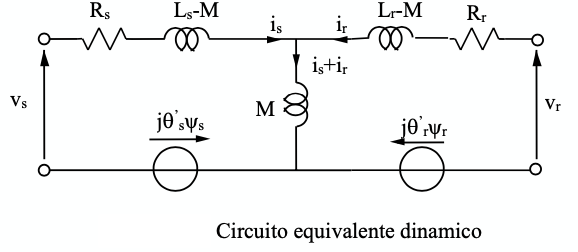

*Img 1 - equivalent 5 parameters dynamic circuit of induction motor*

Starting by the classical 5 parameters model on a *generic* rotating reference frame d-q we have this equations: 


$${\bar{v} }_s =R_s \cdot \bar{i_s } +L_s \cdot p\bar{i_s } +L_m \cdot p\bar{i_r } +j\dot{\theta_s } \cdot \bar{\psi_s }$$
 


$${\bar{v} }_r =R_r \cdot \bar{i_r } +L_r \cdot p\bar{i_r } +L_m \cdot p\bar{i_s } +j\dot{\theta_r } \cdot \bar{\psi_r }$$
 

with

$\bar{v_s } =\sqrt{\frac{2}{3}}\left\lbrack v_a \left(t\right)+v_b \left(t\right)\cdot \alpha +v_c \left(t\right)\cdot \alpha^2 \right\rbrack =V_{\textrm{rms}} \cdot e^{j\omega t} ;\;\bar{i} =I\cdot e^{j\omega t} ;\psi^‾ =\Psi \cdot e^{j\omega t}$ same for the rotoric quantities.

%Alim param
Vrms = 380;
f = 50;
omega = 2*pi*f;
Vmax = sqrt(2)*Vrms;

%Asin motor param
Rs = 0.24;
Ls = 59.4*10^-3;

Rr = 0.175;
Lr = 59.1*10^-3;

Lm = 57*10^-3;
np = 3;
beta = 0.068;
J = 0.4;

%load param
r = 4;  %ratio gearbox
k_comp = 0.009;%torque proportion (quadratic to speed)

%useful stuff
alfa_beta = 0;
T_amp = 2/3;
T_1_amp = 1;
rad_to_rpm = 60/(2*pi);
s = tf('s');

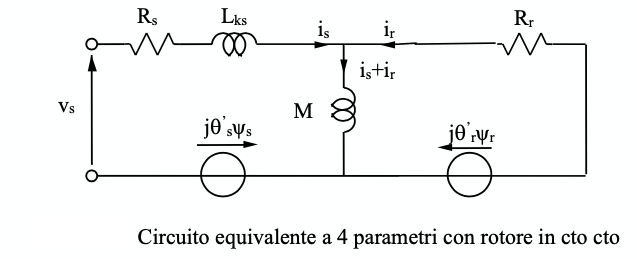

*Img 2 - equivalent 4 parameters dynamic circuit of induction motor* 

First we reduce the system to a 4 parameters model by inserting a ficticious transformer with value k:1 to the rotor end. The parameters will change, but only from the mathematical point of view. If we choose $k=\frac{\textrm{Lm}}{\textrm{Lr}}$ the rotor inductance will be 0 and the other quantitties will assume this values:


$$\frac{\bar{v_r } }{\bar{v_r \prime } }=\frac{\bar{\psi_r } }{\bar{\psi_r \prime } }=\frac{\bar{{i_r }^{\prime } } }{\bar{i_r } }=\frac{1}{k}$$


${R_r }^{\prime } =k^2 \cdot R_r$;  $L_{\textrm{km}} =k\cdot L_m$;  $L_{\textrm{ks}} =L_s -k\cdot L_m$

k_trafo = Lm/Lr;

Lkm = Lm*k_trafo;
Lks = Ls -k_trafo*Lm; 
Rr = (k_trafo^2)*Rr;
Rks = Rs + Rr;

The final set of equations is: (vr is equal to zero because we assume the rotor is closed in shortcircuit)


$${\bar{v} }_s =R_s \cdot \bar{i_s } +p\bar{\psi_s } +j\dot{\theta_s } \cdot \bar{\psi_s }$$
 


$${\bar{v_r } }^{\prime } ={R_r }^{\prime } \cdot {\bar{i_r } }^{\prime } +p\bar{{\psi_r }^{\prime } } +j\dot{\theta_r } \cdot \bar{\psi_r \prime } =0$$



$$\bar{\psi_s } =L_{\mathrm{ks}} \cdot \bar{i_s } +\bar{{\psi_r }^{\prime } }$$



$$\bar{{\psi_r }^{\prime } } =L_{\textrm{km}} \cdot \left(\bar{i_s } +\bar{{i_r }^{\prime } } \right)$$



$$T_e =n_p \cdot \textrm{Im}\left(\bar{i_s } \underline{\psi_s } \right)$$


Then choosing the reference frame in a way that the 'd' axis is coincident with the state space vector of the rotor flux we obtain:


$$v_{\textrm{sd}} =R_{\textrm{ks}} i_{\textrm{sd}} +L_{\textrm{ks}} {\textrm{pi}}_{\textrm{sd}} -\frac{R_r }{L_{\textrm{km}} }\psi_r -\dot{\theta_s } L_{\textrm{ks}} i_{\textrm{sq}}$$



$$v_{\textrm{sq}} =R_{\textrm{ks}} i_{\textrm{sq}} +L_{\textrm{ks}} {\textrm{pi}}_{\textrm{sq}} +\dot{\theta_m } \psi_r +\dot{\theta_s } L_{\textrm{ks}} i_{\textrm{sd}}$$



$$p\psi_r =R_r i_{\textrm{sd}} -\frac{R_r }{L_{\textrm{km}} }\psi_r$$



$$0=R_r i_{\textrm{sq}} -\dot{\theta_r } \psi_r$$



$$T_e =n_p \psi_r i_{\textrm{sq}}$$


We can see how for a constant rotor flux the torque depends only on the isq component of the current and the rotor flux on the other one, i.e. the isd component.

The FOC method is then builded like this where we have:

-  5 PI controller

-  a component that select the operating region for the flux reference

- estimators for flux rotor, position and speed of the reference frame

- power supply 

- sensor for voltage, current consumption and mechanical speed 

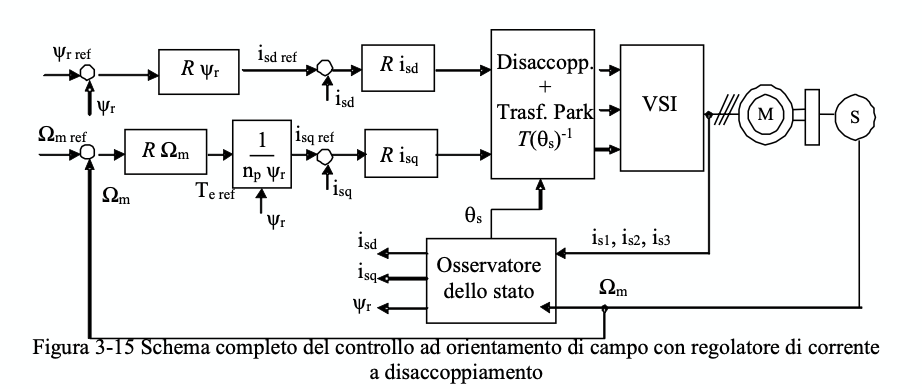

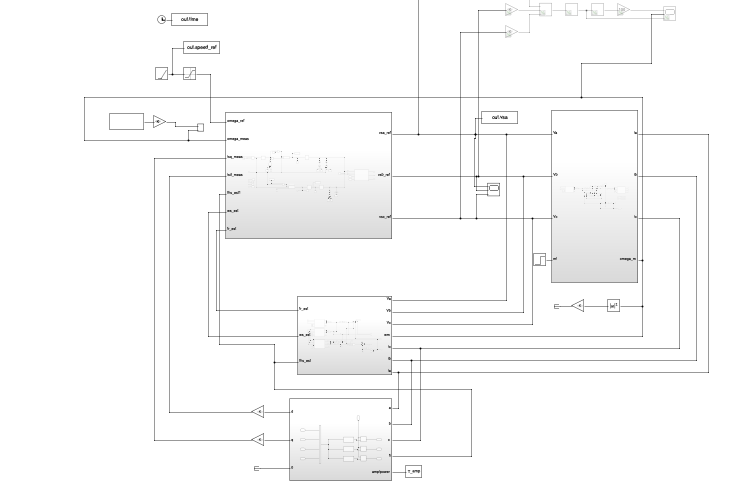

*Img 3 - complete model (FOC top left box, motor top right box, estimator central box, park bottom box)*

I modelled the motor using a stationary reference frame and the control logic using the FOC, to interface the two different system with different reference frame I transform always the voltage and current parameters in the common a,b,c triad, in this way it was like to "really" connect the 3 clamps of the motor to the power supply. Also giving the 3 a,b,c current and shaft speed as output helped me in imaging the motor like a real one, like if have voltage sensors, current sensors and a tachimeter (or an encoder from which I derive speed). 

## Test of the motor without load

First thing we have to do is test the motor without load, this will allow us to see nominal values of flux and speed and then validate our model. 

We know the sinchronus speed of a motor is 

$n_0 =60\cdot \frac{f}{n_p }$[rpm]

so our motor should reach 1000 rpm.

The other parameter I want to check is the stator current. Since without load isq should be 0 and isd should reach $\frac{\psi_r^n }{L_{\textrm{km}} }$. To do this I study the behaviour of stator and rotor flux. 

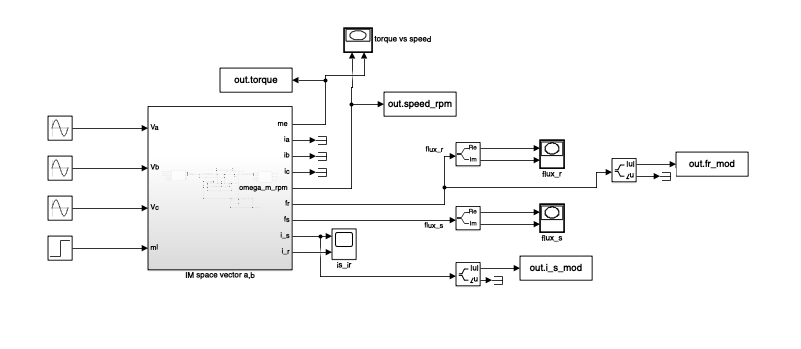

*Img 4 - simulnk scheme of the test without load (ml step = 0)*

n0 = 60*f/np

n0 = 1000

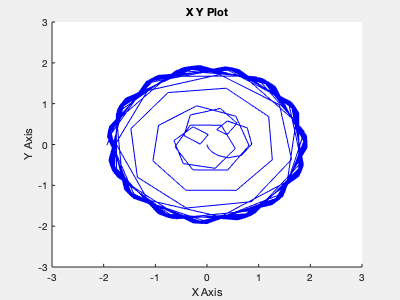

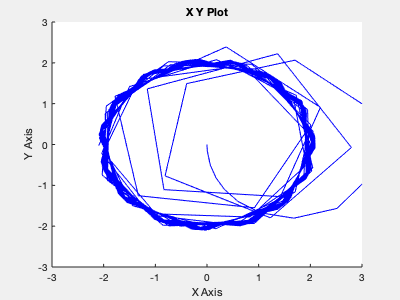

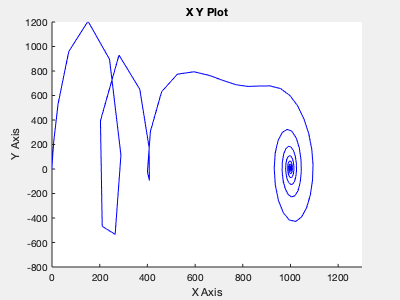

if(see ==1)
open('DZ_AC_ol');
end
out = sim('DZ_AC_ol');

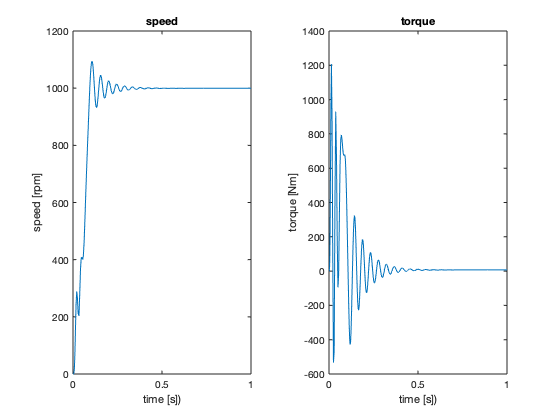

tiledlayout(1,2);
nexttile;
plot(out.time.Data, out.speed_rpm.Data);
title('speed');
ylabel('speed [rpm]');
xlabel('time [s])');
nexttile;
plot(out.time.Data, out.torque.Data);
title('torque');
ylabel('torque [Nm]');
xlabel('time [s])');

After the simulation I obtain this parameters and I can continue in the development of the controller

%save the values
fr_n = out.fr_mod.Data(end)

fr_n = 1.9380

is_min = out.i_s_mod.Data(end)

is_min = 35.2812

isd_n = fr_n/Lkm

isd_n = 35.2528

In this case is_min is equal to isd_n, this is because the motor is without load and then torque and isq component will tend to zero, leaving only the component of the current needed to mantin a costant flux.

## Realization of the simplified scheme

In order to get the first results I simplified the scheme by neglecting some estimators and using the real values coming out of the motor like if I were able to mesure position and intensity of rotor flux. In addition, to simplify the calculation of isd I skipped the use of the estimation of the flux and used the reference constant value, like if the transient was already gone. 

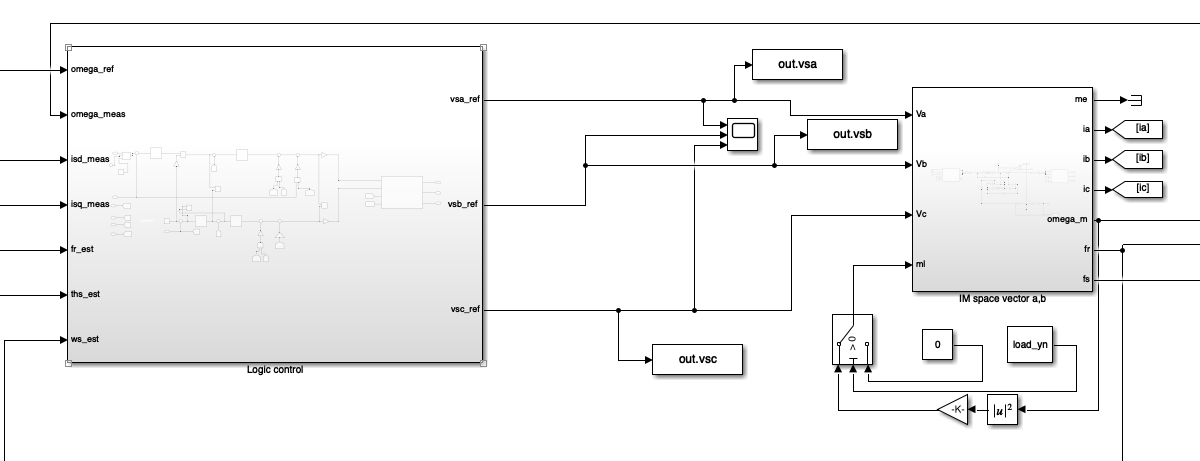

*Img 5 - FOC logic control + IM (zoom on the two components)*

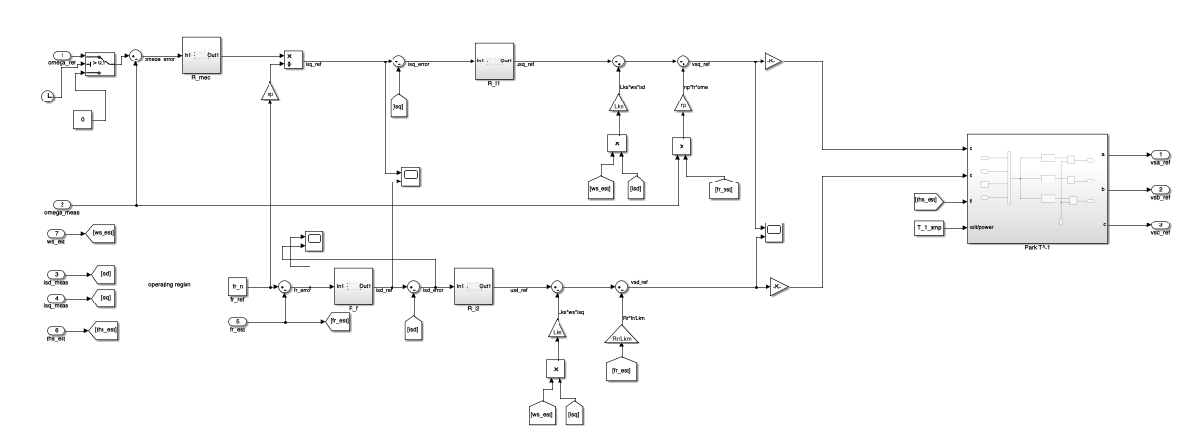

*Img 6 -FOC logic control (easy version)*

I started by the request of one decade faster of the open loop and recursively get the constraints for the internal speed of flux and current loops. To calculate kp and ki values of PI I used the cancellation pole techinque, this way the loop transfer function becomes $\frac{w_c }{s}$ and the closed loop transient will be end after $5\tau =\frac{5}{\omega_c }$ and phase margin will be 90°. 

Both the current loop present the same transfer function $G_I \left(s\right)=\frac{1}{{s\;L}_{\textrm{ks}} +R_{\textrm{ks}} }$ once you remove the coupling terms. 

For the flux regulator  we have this loop, where LI(s) (F_I in MATLAB script) is the closed loop of the current controller. Assuminig the constraint that inner loops are one decade faster we are sure we can neglect it in the regulation of the control law, anyway F_f_real keeps also that loop into account. 

Same consideration are done for the speed regulator. 

close all;
%open loop speed
tau_ol = J/beta;
wc_ol = 1/tau_ol;

%desired speed 
tau_speed = tau_ol/500;
wc_speed = 1/tau_speed;

%desired current isd = isq circuit
%inner loop one decade faster
tau_I = tau_speed/10;
wc_I = 1/tau_I;

G_I = 1/(Rks + s*Lks);
kp_I = wc_I*Lks;
ki_I = wc_I*Rks;
R_I = kp_I + ki_I/s;

F_I = R_I*G_I/(1+R_I*G_I);

%desired flux 
%outer loop wrt isq at least 10 time slower
tau_f = tau_I*85;
wc_f = 1/tau_f;

G_f = Rr/(s+Rr/Lkm);
kp_f = wc_f*1/Rr;
ki_f = wc_f*1/Lkm;
R_f = kp_f + ki_f/s;

F_f = R_f*G_f/(1+ R_f*G_f);

F_f_real = (R_f*F_I*G_f)/(1 + R_f*F_I*G_f);

%desired speed 
G_mec = 1/(s*J +beta);
kp_m = wc_speed*J;
ki_m = wc_speed*beta;
R_mec = kp_m + ki_m/s;

F_mec = (R_mec*G_mec)/(1 + R_mec*G_mec);

F_mec_real = (R_mec*F_I*G_mec)/(1 + R_mec*F_I*G_mec);

The simulaton gived me the required speed but voltage and current were too high, so I decided to relax the constraints until I get a decent value of them. The problem was especially on the starting of the system were I was applying both the reference of flux and speed to the controller. 

Considering the analogy with the DC motor controller scheme and the fact that the I-omega estimator needs a constant current to get the intial value of flux magnitude and position, I implemented the schema giving first the flux reference and then, after 1 tau of the flux loop (when it's already reduced of 63% with respect to final voltage), applying the speed reference. In the case of the profile of the reference speed I started it at time 0 beacause my system was able to overcome the initial delay and error anyway. 

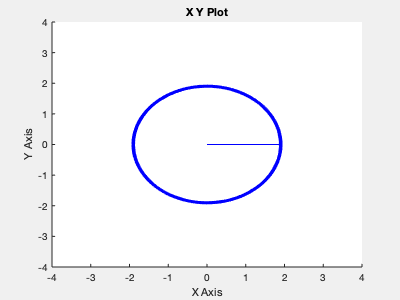

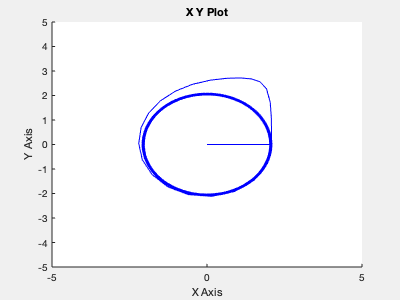

if(see ==1)
open('DZ_AC_easyFOC');
end
ref_speed=n0/rad_to_rpm; %rad/s
load_yn=0;
out = sim('DZ_AC_easyFOC', 'StopTime', '2');

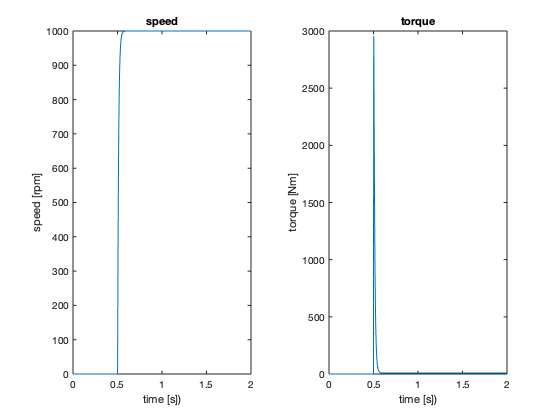

tiledlayout(1,2); 
nexttile;
plot(out.time.Data, out.speed_rpm.Data);
title('speed');
ylabel('speed [rpm]');
xlabel('time [s])');
nexttile;
plot(out.time.Data, out.torque.Data);
title('torque');
ylabel('torque [Nm]');
xlabel('time [s])');

In this phase I add the load, a compressor that generates a torque proportional to the square of the motor shaft speed and started to follow the reference. 

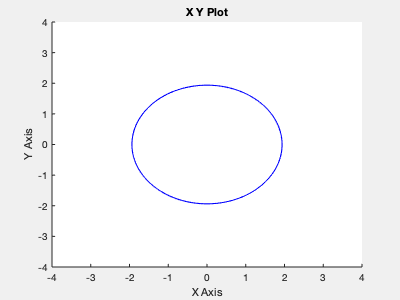

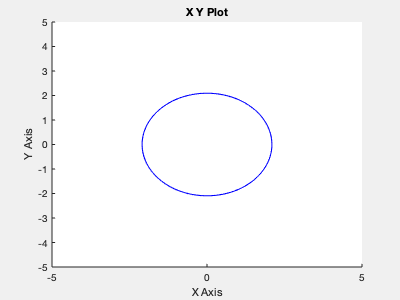

load_yn=1;                  %withload
out = sim('DZ_AC_easyFOC', 'StopTime', '70');

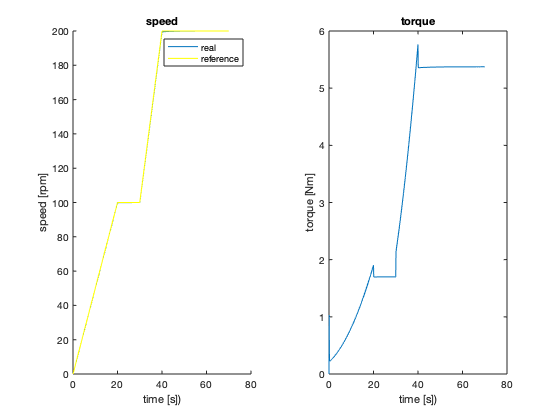

tiledlayout(1,2); 
nexttile;
hold on;
plot(out.time.Data, out.speed_rpm.Data);
plot(out.time.Data, out.speed_ref.Data*n0, 'y');
title('speed');
ylabel('speed [rpm]');
xlabel('time [s])');
legend('real', 'reference');
%plot(out.time.Data, ref_speed*rad_to_rpm*ones(size(out.time.Data)));
hold off;
nexttile;
plot(out.time.Data, out.torque.Data);
title('torque');
ylabel('torque [Nm]');
xlabel('time [s])');

At this point becomes important the amplitude of the voltage we are applying to the motor, since too fast system could lead to too high voltage. Vrms is 380 V  then the maximum value the system can substain is $\pm V_{\max }$= 537 V

vsa_max = max(max(out.vsa.Data), -min(out.vsa.Data))

vsa_max = 365.6508

vsb_max = max(max(out.vsb.Data), -min(out.vsb.Data))

vsb_max = 182.8254

vsc_max = max(max(out.vsc.Data), -min(out.vsc.Data))

vsc_max = 182.8254

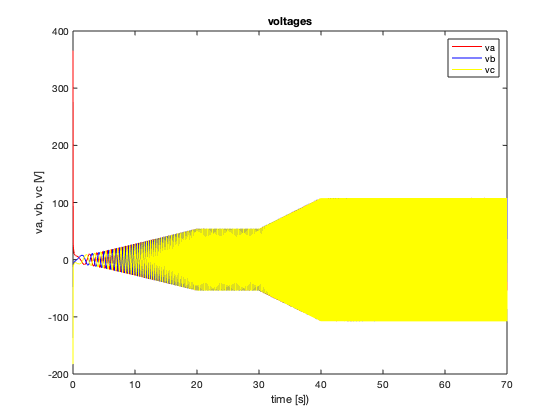

figure;
plot(out.time.Data, out.vsa.Data, 'r');
hold on;
plot(out.time.Data, out.vsb.Data, 'b');
plot(out.time.Data, out.vsc.Data, 'y');
title('voltages');
ylabel('va, vb, vc [V]');
xlabel('time [s])');
legend('va', 'vb', 'vc');

As I said before, if values are too high at the beginning, where speed and torque are low, then we will need to relax flux regulator controller. 

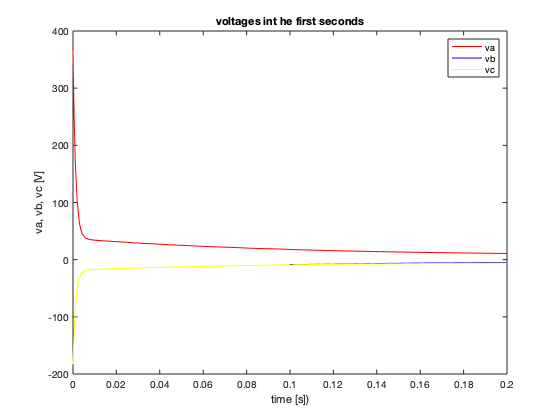

figure;
plot(out.time.Data, out.vsa.Data, 'r');
hold on;
plot(out.time.Data, out.vsb.Data, 'b');
plot(out.time.Data, out.vsc.Data, 'y');
xlim([0 0.2]);
title('voltages int he first seconds');
ylabel('va, vb, vc [V]');
xlabel('time [s])');
legend('va', 'vb', 'vc');

## Implementation of the estimators

I have implemented a I-omega estimator to obtain flux module and position, it also computes the speed of the rotating reference. In addition I implemented also a VI estimator to do confrontations. New scheme, more complex but it still works. 

At this point, the choice of applying a costant current at the beginning helps a lot in the evaluation of the flux module and speed of the rotating reference frame.

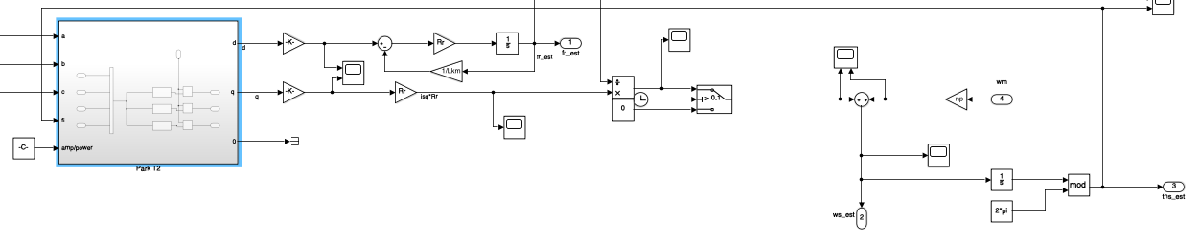

*Img 7 - I-omega estimator for flux, position and speed of reference frame *

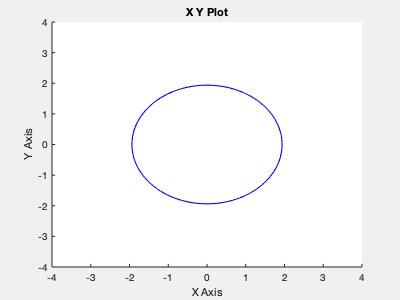

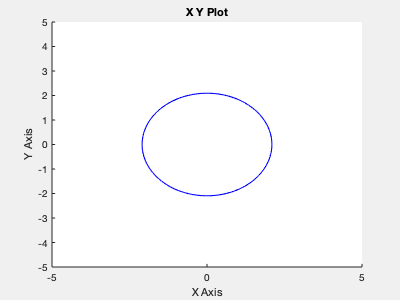

if(see ==1)
open('DZ_AC_estFOC');
end
out = sim('DZ_AC_estFOC', 'StopTime', '70');

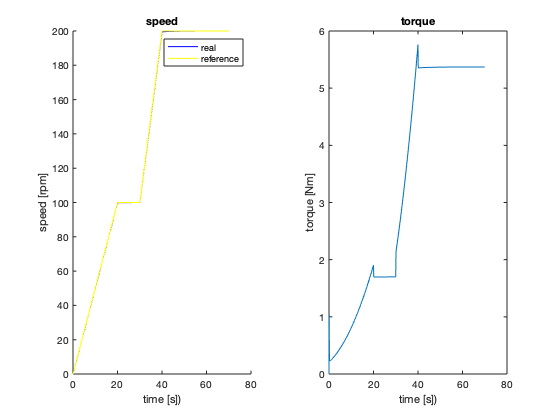

tiledlayout(1,2); 
nexttile;
hold on;
plot(out.time.Data, out.speed_rpm.Data, 'b');
plot(out.time.Data, out.speed_ref.Data*n0, 'y');
title('speed');
ylabel('speed [rpm]');
xlabel('time [s])');
legend('real', 'reference');
hold off;
nexttile;
plot(out.time.Data, out.torque.Data);
title('torque');
ylabel('torque [Nm]');
xlabel('time [s])');

We can see that the controller follows really good the reference speed. Furthermore we are going to look the difference between extimated and real flux and we see they are close so our estimator works well. 

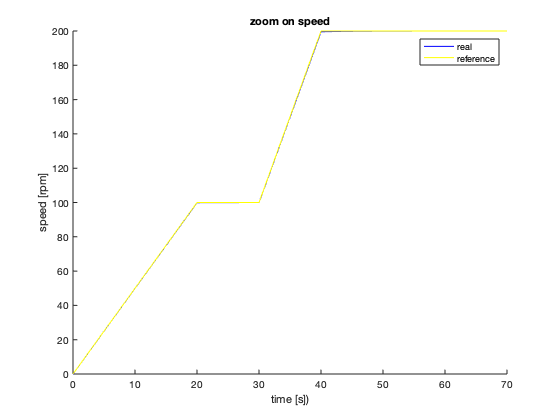

figure;
hold on;
plot(out.time.Data, out.speed_rpm.Data, 'b');
plot(out.time.Data, out.speed_ref.Data*n0, 'y');
hold off;
title('zoom on speed');
ylabel('speed [rpm]');
xlabel('time [s])');
legend('real', 'reference');

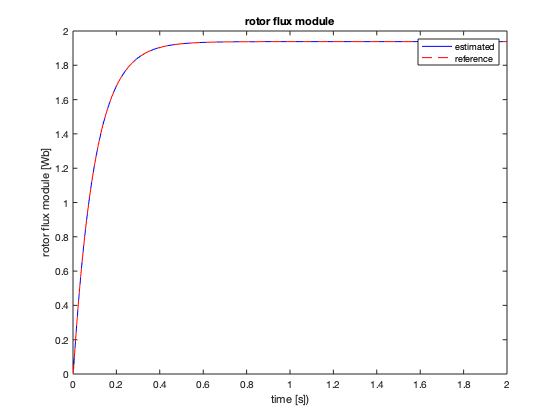

figure;
plot(out.time.Data, out.fr_est.Data, 'b', out.time.Data, out.fr_real.Data, 'r--');
title('rotor flux module');
ylabel('rotor flux module [Wb]');
xlabel('time [s])');
legend('estimated', 'reference');
xlim([0 2]);

Last index I want to check is the maximum voltage, to see if we are not exceding the capability of the power supply (380 Vrms -> 537 V). 

Vsamax = max(out.vsa.Data)

Vsamax = 365.6508

## Expansion of the operating region 

Increasing the speed the $\omega *\psi_r$ coponent on the voltage keeps increasing and Vs will soon reach it's maximum value, due to isolation and power supply limits. However, we can try to keep this voltage value fixed and increasing the speed by decreasing the rotor flux. To do so we use a switch controlled by the speed, under the reference we use the nominal value, above we will start decreasing it with inverse proportion to the speed. By doing so also isd will decrease and we decide to keep the other current component constant to its nominal value, in order to not get excessive thermal effects. The isq current value is computed by dividing the torque by the nominal reference flux, like if we were still under the base speed. 

I tried with an increasing speeds until I reached the maximum voltage, then I used that value as base speed. This allowed me to go over the base speed. 

For the purpose of the project this was not necessary, in fact we never reach that value in the range of speed requested by the problem. Anyway I tried it applying a constant torque of 100 Nm, we can see in the graphs of rotor and stator flux how they decrease, this means it's working.

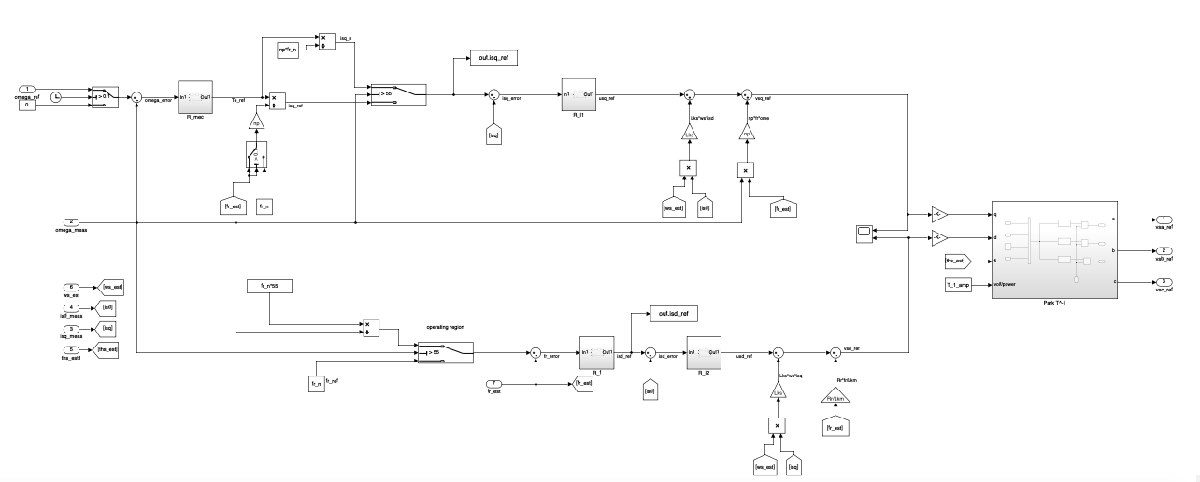

*Img 8 - FOC logic control with extended region over base speed*

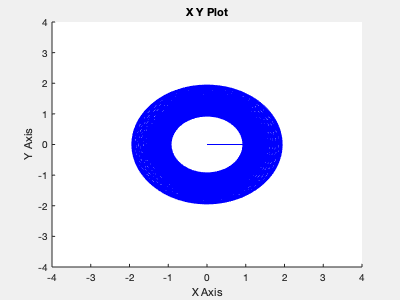

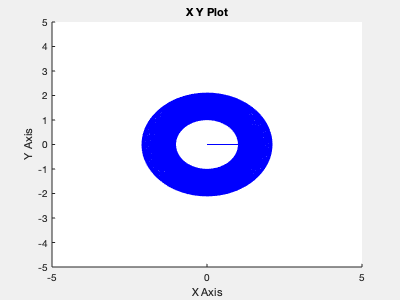

if(see ==1)
open('DZ_AC_extFOC');
end
out = sim('DZ_AC_extFOC');

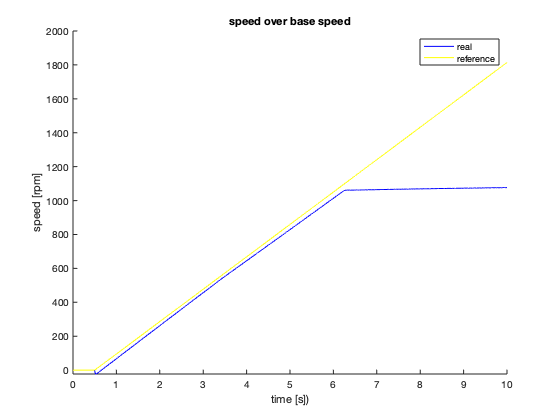

figure;
hold on;
plot(out.time.Data, out.speed_rpm.Data, 'b');
plot(out.time.Data, out.speed_ref.Data*rad_to_rpm, 'y');
hold off;
title('speed over base speed');
ylabel('speed [rpm]');
xlabel('time [s])');
legend('real', 'reference');

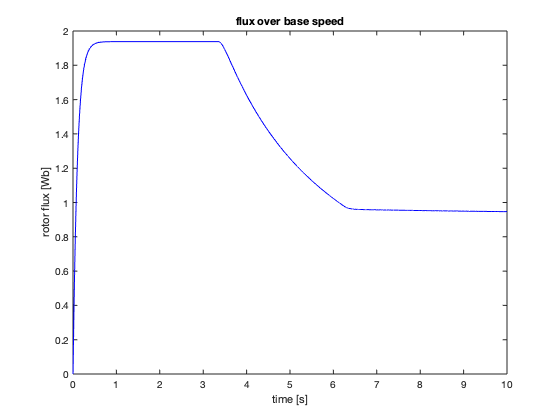

figure;
plot(out.time.Data, out.fr_est.Data, 'b');
title('flux over base speed');
xlabel('time [s]');
ylabel('rotor flux [Wb]');

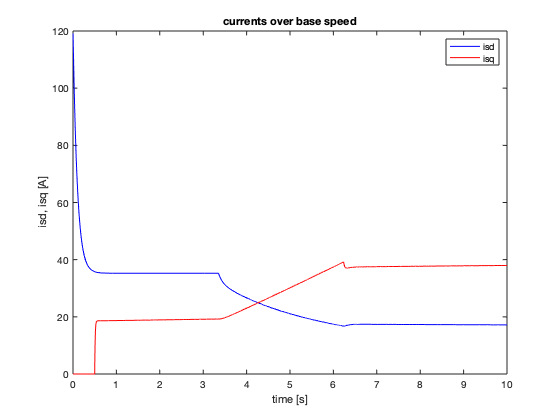

figure;
plot(out.time.Data, out.isd_ref.Data, 'b', out.time.Data, out.isq_ref.Data, 'r');
title('currents over base speed');
xlabel('time [s]');
ylabel('isd, isq [A]');
legend('isd', 'isq');